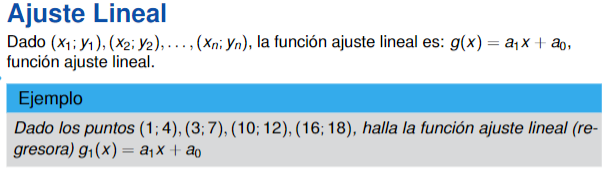

Ajuste Lineal con Polyfit

x=[1 3 10 16]'

x =      1
     3
    10
    16


y=[4 7 12 18]'

y =      4
     7
    12
    18


g1=polyfit(x,y,1)

g1 =    0.890070921985816   3.574468085106386


xx=linspace(1,20,50);
yy=polyval(g1,xx);
plot(x,y,'ob',xx,yy,'r')
grid on
title('Ajuste Lineal')

Ajuste Lineal de otra forma con Matlab

M = [x ones(4,1)]

M =      1     1
     3     1
    10     1
    16     1


u = inv(M'*M)*M'*y

u =    0.890070921985815
   3.574468085106384


La bondad del ajuste lineal es de la siguiente forma

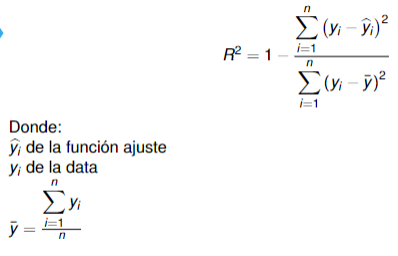

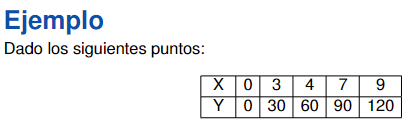

Determinar la calidad del ajuste lineal

x=[0 3 4 7 9]'

x =      0
     3
     4
     7
     9


y=[0 30 60 90 120]'

y =      0
    30
    60
    90
   120


p1=polyfit(x,y,1)

p1 =   13.414634146341461  -1.707317073170732


yc=polyval(p1,x)

yc = 1.0e+02 *

  -0.017073170731707
   0.385365853658536
   0.519512195121951
   0.921951219512195
   1.190243902439024


R2 = 1 - sum((y - yc).^2)/sum((y - mean(y)).^2)

R2 =    0.983739837398374


xx=linspace(0,10,50);
yy=polyval(p1,xx);
plot(x,y,'ob',xx,yy,'r')
grid on
title('Ajuste Lineal')


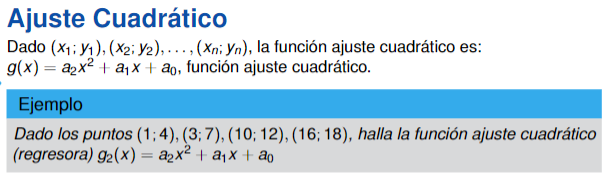

x=[1 3 10 16]'

x =      1
     3
    10
    16


y=[4 7 12 18]'

y =      4
     7
    12
    18


M=[x.^2 x ones(4,1)]

M =      1     1     1
     9     3     1
   100    10     1
   256    16     1


u=inv(M'*M)*M'*y

u =    0.003026220112067
   0.839011506052448
   3.680514564352628


u=polyfit(x,y,2)

u =    0.003026220112066   0.839011506052441   3.680514564352623


xx=linspace(-10,20,50);
yy=polyval(u,xx);
plot(xx,yy,'r',x,y,'ob')
grid on


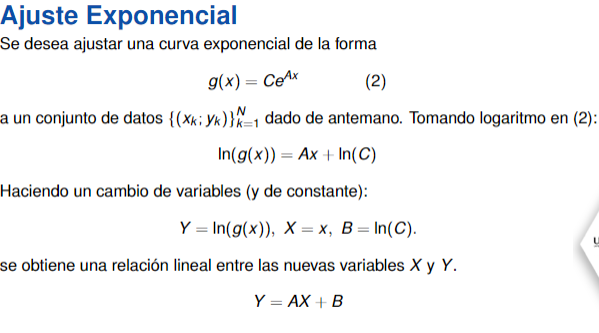

x1=[1 3 10 16]'

x1 =      1
     3
    10
    16


y1=[4 7 12 18]'

y1 =      4
     7
    12
    18


X=x1;
Y=log(y1)

Y =    1.386294361119891
   1.945910149055313
   2.484906649788000
   2.890371757896165


g1=polyfit(X,Y,1)

g1 =    0.092290195379852   1.484694264115950


A=g1(1)

A =    0.092290195379852


C=exp(g1(2))

C =    4.413615805747212


syms x
g= @(x)(C*exp(A*x))

g = function_handle with value:
    @(x)(C*exp(A*x))


xx=linspace(1,16,50);
yy=g(xx);
plot(xx,yy,'r',x1,y1,'ob')
grid on

Otra prueba con accidents

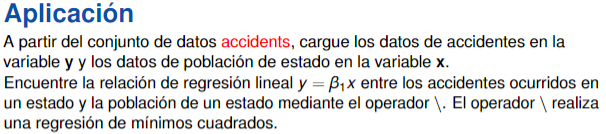

load accidents
x = hwydata(:,14); %Poblacion por estado
y = hwydata(:,4); %Accidentes por estado
format long
b1 = x\y

b1 =      1.372716735564871e-04


yc1 = b1*x;
scatter(x,y,'r')
hold on
plot(x,yc1,'b')
xlabel('Poblacion del estado')
ylabel('Accidentes de trafico mortales por estado')
title('Relacion de regresion lineal entre accidentes y poblacion')
grid on

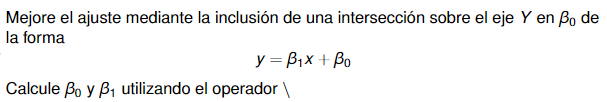

X = [ones(length(x),1) x]

X =            1      493782
           1      572059
           1      608827
           1      626932
           1      642200
           1      754844
           1      783600
           1      902195
           1     1048319
           1     1211537


format long
b = X\y

b = 1.0e+02 *

   1.427120171726538
   0.000001256394274


yc2 = X*b;
plot(x,yc2,'--')
legend('Data','Slope','Slope & Intercept');

Calidad de la regresión lineal y su correlación

Rsq1 = 1 - sum((y - yc1).^2)/sum((y - mean(y)).^2)

Rsq1 =    0.822235650485566


Rsq2 =    0.838210531103428


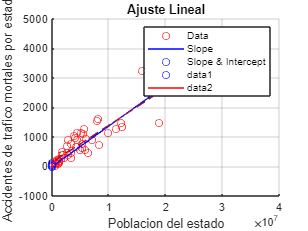

Rsq2 = 1 - sum((y - yc2).^2)/sum((y - mean(y)).^2)